
OriginalImagePath = "verifytest.jpg";

%Verify that the image is an ok Size. This is mostly done to evade long
%running time since the program can handle almost any size
ImageToUse = verifyImage("verifytest.jpg");

row = 20

col = 10

colors = 3

Image is smaller than 100px, scaling performed. consider using larger picture




%%choose the size of the tiles that divedes the original image into
%%sections
%%larger values may give a bad result and smaller values my affect the
%%performance of structural similarity
TileSize = 5;

%%choose how many images you want in the imageDataBase
DbSize= 100;

%%Create array from folder containing ImageDatabase, the folder needs to
%%contain file of the format jpg.
myCellArray = createCellArrayFromDir("flower/"); %1.1

now reading flower/flower_0000.jpg
now reading flower/flower_0001.jpg
now reading flower/flower_0002.jpg
now reading flower/flower_0003.jpg
now reading flower/flower_0004.jpg
now reading flower/flower_0005.jpg
now reading flower/flower_0006.jpg
now reading flower/flower_0007.jpg
now reading flower/flower_0008.jpg
now reading flower/flower_0009.jpg
now reading flower/flower_0010.jpg
now reading flower/flower_0011.jpg
now reading flower/flower_0012.jpg
now reading flower/flower_0013.jpg
now reading flower/flower_0014.jpg
now reading flower/flower_0015.jpg
now reading flower/flower_0016.jpg
now reading flower/flower_0017.jpg
now reading flower/flower_0018.jpg
now reading flower/flower_0019.jpg
now reading flower/flower_0020.jpg
now reading flower/flower_0021.jpg
now reading flower/flower_0022.jpg
now reading flower/flower_0023.jpg
now reading flower/flower_0024.jpg
now reading flower/flower_0025.jpg
now reading flower/flower_0026.jpg
now reading flower/flower_0027.jpg
now reading flower/f

now reading flower/flower_0834.jpg
now reading flower/flower_0835.jpg
now reading flower/flower_0836.jpg
now reading flower/flower_0837.jpg
now reading flower/flower_0838.jpg
now reading flower/flower_0839.jpg
now reading flower/flower_0840.jpg
now reading flower/flower_0841.jpg
now reading flower/flower_0842.jpg


inpict = 200×100×3 uint8 array
inpict(:,:,1) =

   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   205   205   205   205   205   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203   203
   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   

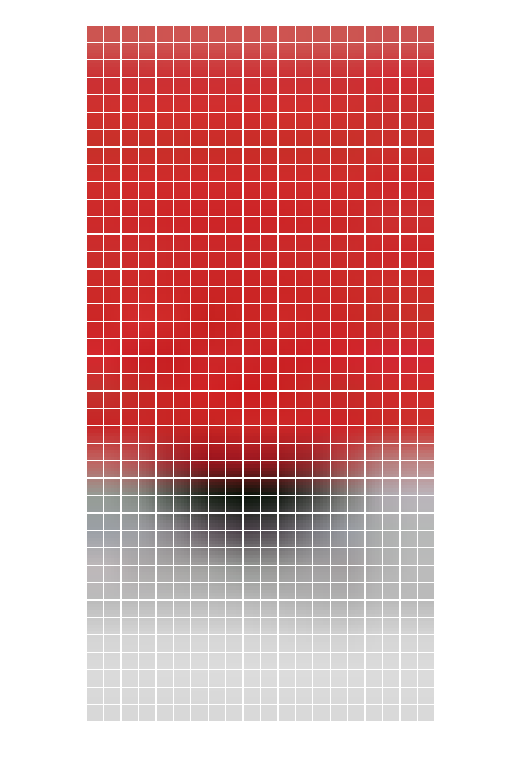

%%Reduces Array from elements in directory to 100 using K-means must be
%%atleast 100 elements in the array
kmeanedArray = KmeansOnCellArray(myCellArray,DbSize);%1.2



%%converts image to namearray consisting of reduced database
%%choose either ssim or not

%%using just tiles
nameArray= NamearrayUsingTiles(ImageToUse,kmeanedArray,5);


%%accounting for structural similarity
%nameArray= reconstructWithSsim(ImageToUse,kmeanedArray,5);

%%choose reproduction mode 

%%regular reproduction
result = reconstructFromNameArray(nameArray,1);


Repoduced =

     []



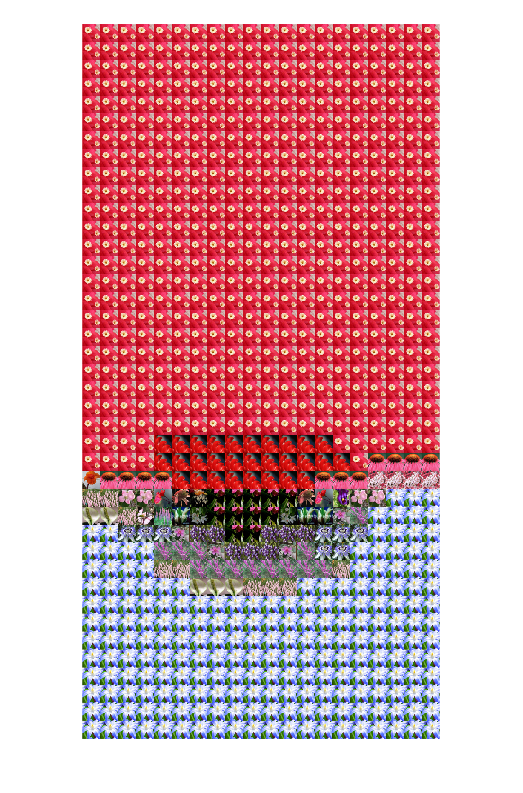


%%areas containing same images is replaced with larger images
%result = reconstructFromNameArrayDifferentSizes(nameArray)

imshow(result)